% ejemplo de diseño de filtro digital
% filipuzzi, fernando rafael
% fecha: 20230313
% matlab2022b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Diseño del filtro Pasa Altos**

**Parámetros de diseño**

fm=12760;             % Hz,  Frecuencia de Muestreo
fMAX=fm/2;
                                  fc=2873.5;
fp=1000 ;                               fs=2873.5 ;              
Ap=0.5 ;                                As=15 ;                             

**Diseño del filtro**

- Transformar las caracteristicas de frecuencia de paso bajo a paso bajo normalizado

Fc=fc/fc;
Fs=fs/fc;
Fp=fp/fc;

- Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

N =      5


- Función de transferencia y respuesta en frecuencia

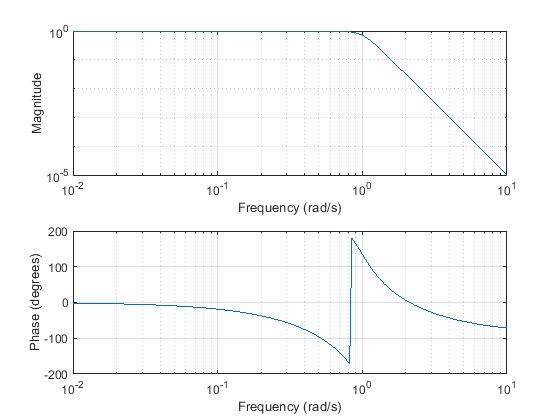

[BS, AS]=mi_butter(N);
freqs(BS,AS);

- Transformación en frecuencia

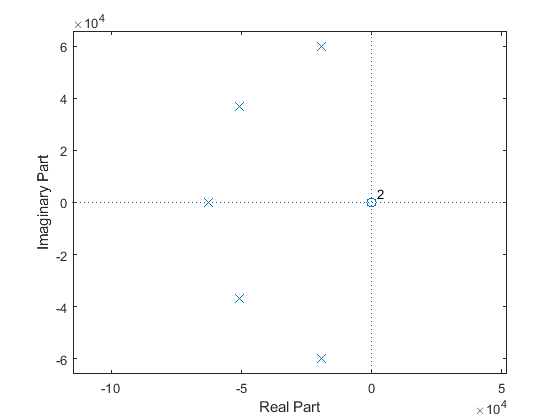

[Bs, As] = lp2hp(BS,AS,2*pi*fc); 
figure, zplane( [zeros(1, N- length(Bs)+1) Bs], [zeros(1, N- length(As)+1) As] );

**Transformación bilinear - matlab.**

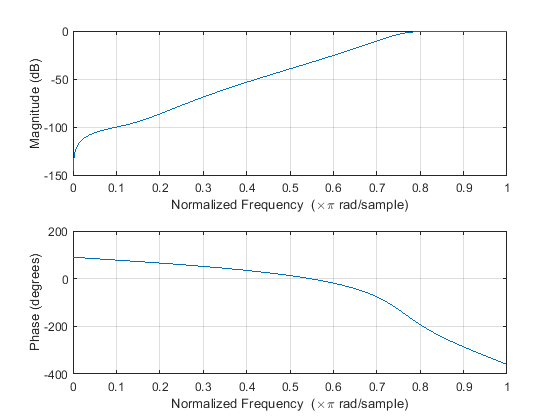

mapeo=4;

switch mapeo
    case 1
        [Bz, Az]=mi_integral(Bs, As, fm);
    case 2
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case 3
        [Bz, Az]=impinvar(Bs, As, fm);
    case 4
        [Bz, Az]=mi_bilinear(Bs, As, fm);
    case 5
        [Bz, Az]=bilinear(Bs, As, fm);        
end
m=max( abs([ Bz, Az ]) );
Bz=Bz/m;
Az=Az/m;
Bz=Bz/Az(1);
Az=Az/Az(1);
freqz(Bz,Az,2048);

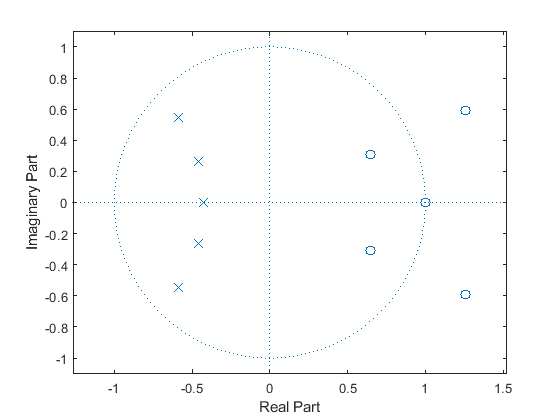



figure, zplane( [ Bz zeros(1, N- length(Bz)+1)], [Az zeros(1, N- length(Az)+1) ] );

**Generación de la linea para inicializar el callback de simulink**

PRECISION_STM32=6;
to_simulink(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Pasa Alto', mapeo)

ans =     '	%Filtro IIR - Pasa Alto -  
     	%Orden: 5
     	%Frecuencia de Muestreo: 12760 (Hz)
     	Fm=12760;
     	ORDEN=5;
     	coef_x= [0.00317919,-0.0153179,0.0303468,-0.0303468,0.0153179, ...
     			-0.00317919];
     	coef_y= [-1,-2.51821,-2.89017,-1.76705,-0.568497, ...
     			-0.0760116];'


**Generación de la linea para la fpga**

Nbits=64;
Qbits=32;
to_fpga(Bz, Az, N, fm, Qbits,Nbits, 'IIR - Pasa Alto', mapeo)

ans =     '//Filtro IIR - Pasa Alto - 
     //Orden: 5
     //Frecuencia de Muestreo: 12760 (Hz)
     assign dx0=64'0x0000000000D059F9;assign dx1=64'0xFFFFFFFFFC141FF7;assign dx2=64'0x0000000007C4CF2B;assign dx3=64'0xFFFFFFFFF83B30D6; 
     			assign dx4=64'0x0000000003EBE00A;assign dx5=64'0xFFFFFFFFFF2FA608;
     assign dy1=64'0xFFFFFFFD7B56B6E7;assign dy2=64'0xFFFFFFFD1C1D986B;assign dy3=64'0xFFFFFFFE3BA27A87; 
     			assign dy4=64'0xFFFFFFFF6E76F932;assign dy5=64'0xFFFFFFFFEC8A81A1;'
